# Live Script Version of Tourette Data Analysis Flow

## Preprocess Collected Data

The genericPreprocessing Script will process all data (DBS Recording, EMG Recording, and Video Recording) and structure them in a format readable to user. No analysis and no modification is done to the actual data. The only modification is video file filename. Please modify the first section as according to the recording meta data. 

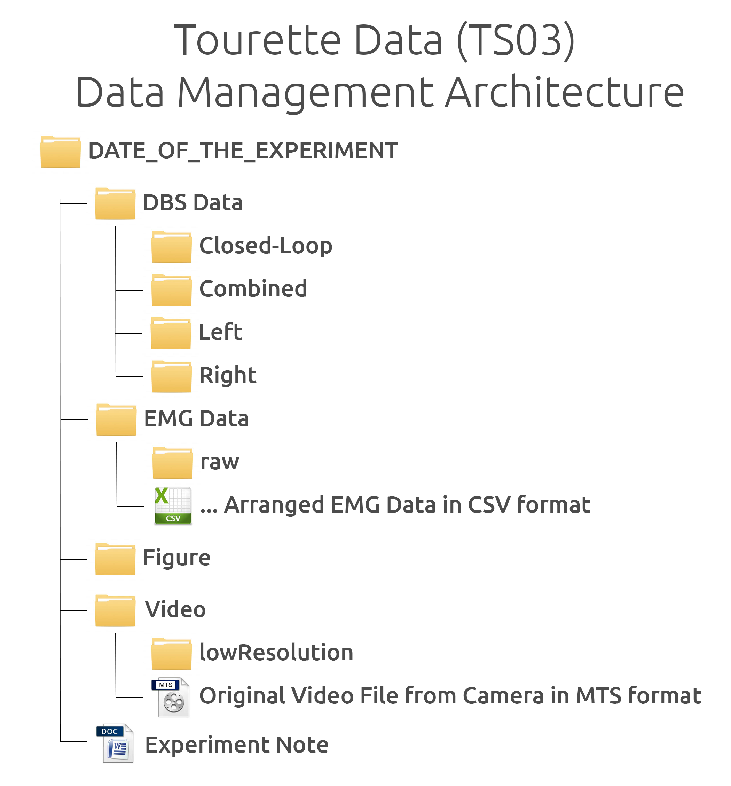

This image indicated the standard data format prior to preprocessing, and the detail placement is disccused below:

    1. DBS Data (No file are stored in this root folder)

        1.1. Closed-Loop (This folder contain **.xml** and **.txt** file when performing closed-loop frequency sweep, or other non-experiment related recording)

        1.2. Combined (This folder contain nothing prior to processing - This folder will contain the renamed and organized data from *"Left"* and *"Right"* folder)

        1.3. Left (This folder contain raw recording obtained from Left-side PC+S device from the patient through sensing programmer)

        1.4 Right (This folder contain raw recording obtained from Right-side PC+S device from the patient through sensing programmer)

    2. EMG Data (The processed EMG Data in **.csv** format will be stored in *"EMG Data"* root folder)

        2.1. raw (This folder contain raw **.hpf** file obtained from Delsys EMG software)

    3. Figure (This folder contain nothing prior to processing and after processing. The analysis will output image to this folder)

    4. Video (The raw **.MTS** video file will be stored in the root folder)

        4.1 lowResolution (This folder contain nothing prior to processing - the downsampled low resolution video in **.avi** format will be stored here)

edit genericPreprocessing

## Synchronize Video / EMG / DBS data

The Graphical User Interface developed is solely used for Tourette project, as other projects does not maintain the same Data Management Architecture. The process flow of this program is outlined below:

1. Sync Video with EMG Data

    1.1. Play Video with "Play Video" button. 

    1.2. When see the moment for Synchronize Data (Beginning of the LED flash, hand movement, etc.), click "Stop Video" button and then click "Select LED Time". 

    1.3. In the selection box below the video, select the EMG number in which you based your synchronizing marker on (Most of the time it will be EMG 01 and that is the Sync Box marker). Use "Zoom In" function to select precise window for sync pulse.

    1.4 Click "Select Sync Pulse" and move the cursor to the place at which you believe the video is corresponding to, then clicked any mouse button. 

    1.5 Verify that "EMG Bias" is shown in the middle text window, indicating the synchronizing process for Video and EMG is completed.

2. Sync EMG Data with DBS Data

    2.1. Use "Zoom In" function in all 3 graphes on the right side to find the precise time-point that the synchronizing pulse occur. Select the correct EMG number in which you can clearly identify the DBS sync pulse in the EMG signal. This is usually EMG 02 or EMG 03 (neck electrode). 

    2.2. Click "EMG Marker", and select the timepoint that sync pulse occur on Top Right graph (could be the first pulse or last pulse, but it must be precisely selected). You need to click twice, the first timepoint indicate the sync pulse from Left INS, and the second timepoint indicate the sync pulse from Right INS. The order must be correct (Left, then Right). If you don't know whether the first pulse is coming from Left device or Right device, check **"Experiment Note" **in the same folder to see if the note is written. If no note is written, try "Right First, then Left Second" order and verify in "Run Video" option. If The order is accurate, you will see obvious problem in Spectrogram display (No synchronization). 

    2.3 Click "Left DBS Marker", and select the timepoint that sync pulse occur on Mid Right graph. 

    2.4 Click "Right DBS Marker", and select the timepoint that sync pulse occur on Bottom Right graph. 

    2.5 After everything, click "Store Information"

utility = SyncData;
utility = renderData(utility);

Delsys = utility.Data.Delsys;
Left_DBS = utility.Data.Left_DBS;
Right_DBS = utility.Data.Right_DBS;
Marker = utility.Marker;
EMG_Bias = utility.EMG_Bias;
DBS_Bias = utility.DBS_Bias;
save([utility.PathName,'../Processed_',utility.FileName(1:end-4),'.mat'],'Delsys','Left_DBS','Right_DBS','Marker','EMG_Bias','DBS_Bias');